fs = 48000;
recorder_object = audiorecorder(fs,16,1);
record(recorder_object);

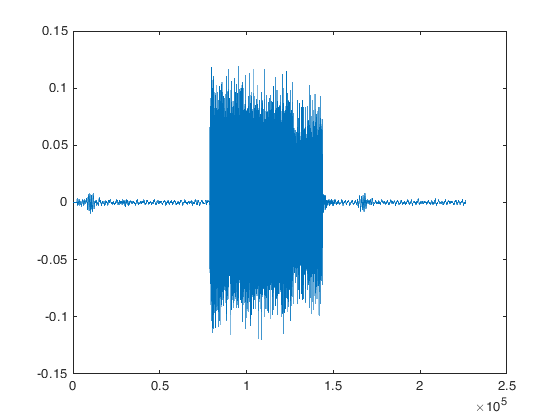

stop(recorder_object);
message_response = getaudiodata(recorder_object);
plot(message_response);

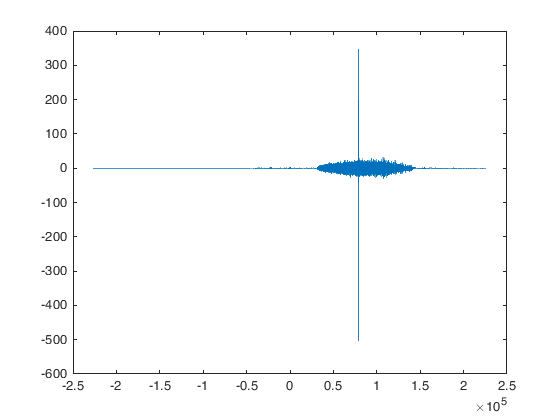

[r, lags] = xcorr(message_response, white_noise);
plot(lags, r);

[peak, ii] = max(abs(r));
start_position = lags(ii);
noise_response = message_response(start_position: ...
    start_position + length(white_noise));
channel_response = fftshift(abs(fft(noise_response)));
signal = message_response(start_position:end);